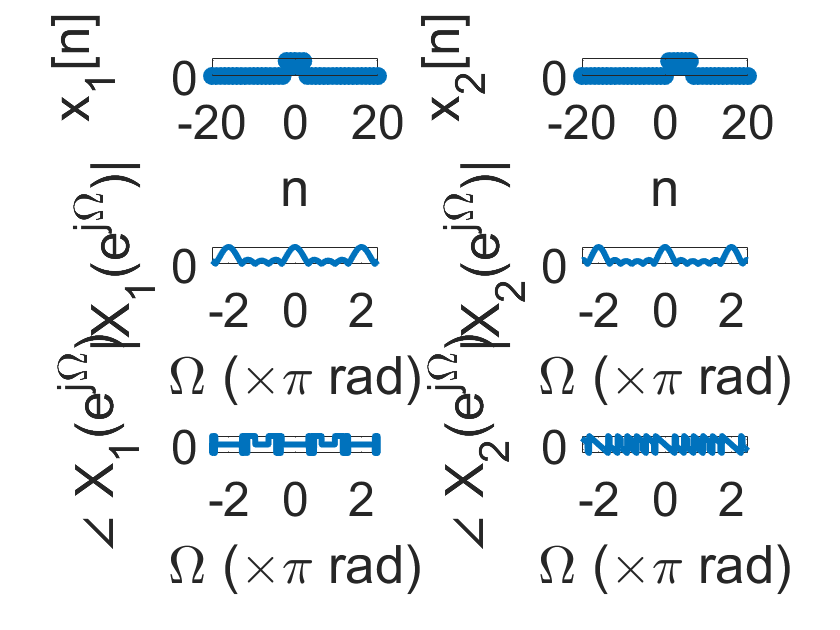

% Plotting the spectrum of a discrete-time rectangular pulse
n=-20:20;
w=-2.5*pi:.01:2.5*pi;
x1=zeros(size(n));
x2=zeros(size(n));
x1(n>=-2 & n<=2)=1;
x2(22:27)=1;
X1=dtft(n,x1,w);
X2=dtft(n,x2,w);
subplot(3,2,1)
stem(n,x1,'linewidth',3);
set(gca,'fontsize',24)
axis([-20 20 0 1.2])
xlabel('n')
ylabel('x_1[n]')
subplot(3,2,2)
stem(n,x2,'linewidth',3);
set(gca,'fontsize',24)
axis([-20 20 0 1.2])
xlabel('n')
ylabel('x_2[n]')
subplot(3,2,3)
plot(w/pi,abs(X1),'linewidth',3);
set(gca,'fontsize',24)
xlabel('\Omega (\times\pi rad)')
ylabel('|X_1(e^{j\Omega})|')
subplot(3,2,5)
plot(w/pi,angle(X1),'linewidth',3);
set(gca,'fontsize',24)
xlabel('\Omega (\times\pi rad)')
ylabel('\angle X_1(e^{j\Omega})')
subplot(3,2,4)
plot(w/pi,abs(X2),'linewidth',3);
set(gca,'fontsize',24)
xlabel('\Omega (\times\pi rad)')
ylabel('|X_2(e^{j\Omega})|')
subplot(3,2,6)
plot(w/pi,angle(X2),'linewidth',3);
set(gca,'fontsize',24)
xlabel('\Omega (\times\pi rad)')
ylabel('\angle X_2(e^{j\Omega})')